### Project - Part 2

### Experimental data 

clear
close all
[ident_data, valid_data, ...
 u_ident, y_ident, ...
 u_valid, y_valid, Ts] = get_data('iddata-20.mat');

#### Identification set

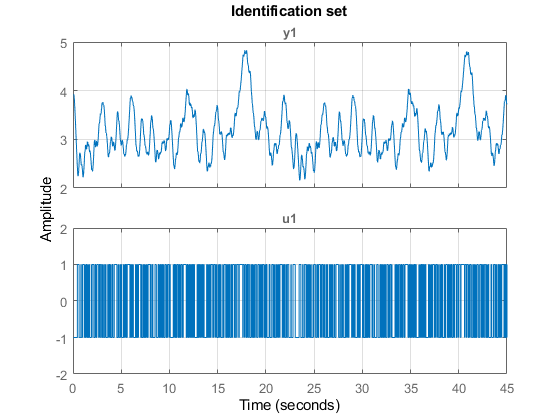

plot(ident_data);
axis([0 Ts*size(u_ident, 1) min(u_ident)-1 max(u_ident)+1]);
title('Identification set'); grid;

#### Validation set

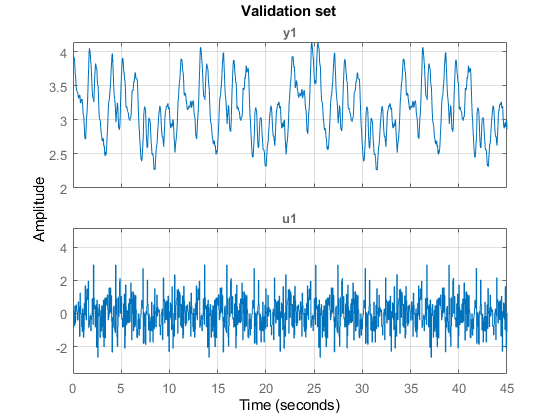

plot(valid_data);
axis([0 Ts*size(u_valid, 1) min(u_valid)-1 max(y_valid)+1]);
title('Validation set'); grid;

### The parameters that will be used for tuning

Visual representation of the number of parameters depending on $\textrm{na}$, $\textrm{nb}$ and $m$.

max_na_nb = 3; max_m = 5;
N = size(u_valid, 1);
combs = get_param_combs(max_na_nb, max_m, N);
results = array2table([combs zeros(size(combs, 1), 4)]);
results.Properties.VariableNames(1:8) = ...
    {'na','nb','m','nr parameters', ...
    'mse ident pred', 'mse valid pred', 'mse ident sim', 'mse valid sim'};
results

results = 41×8 table
    na    nb    m    nr parameters    mse ident pred    mse valid pred    mse ident sim    mse valid sim
    __    __    _    _____________    ______________    ______________    _____________    _____________

    1     1     1          3                0                 0                 0                0      
    2     1     1          4                0                 0                 0                0      
    3     1     1          5                0                 0                 0                0      
    1     2     1          4                0                 0                 0                0      
    2     2     1          5                0                 0             

% for testing only three cases
% results(4:end, : ) = [];
% results

### Tuning results

for i = 1 : size(results, 1)
    na = results{i, "na"};
    nb = results{i, "nb"};
    m = results{i, "m"};
  
    % prediction mode
    theta_pred = get_theta(u_ident, y_ident, m, na, nb);
    
    y_hat_ident_pred = get_y_hat(u_ident, y_ident, theta_pred, m, na, nb);
    y_hat_valid_pred = get_y_hat(u_valid, y_valid, theta_pred, m, na, nb);
    
    results.("mse ident pred")(i) = get_mse(y_ident, y_hat_ident_pred);
    results.("mse valid pred")(i) = get_mse(y_valid, y_hat_valid_pred);
    
    
    % simulation mode
    theta_sim = get_theta(u_ident, y_hat_ident_pred, m, na, nb);
    
    y_hat_ident_sim = get_y_hat(u_ident, y_ident, theta_sim, m, na, nb);
    y_hat_valid_sim = get_y_hat(u_valid, y_valid, theta_sim, m, na, nb);
    
    results.("mse ident sim")(i) = get_mse(y_ident, y_hat_ident_sim);
    results.("mse valid sim")(i) = get_mse(y_valid, y_hat_valid_sim);
    
    sprintf(['Done for na=', num2str(na), ' nb=', num2str(nb), ' m=', num2str(m)])
end

ans = 'Done for na=1 nb=1 m=1'

ans = 'Done for na=2 nb=1 m=1'

ans = 'Done for na=3 nb=1 m=1'

ans = 'Done for na=1 nb=2 m=1'

ans = 'Done for na=2 nb=2 m=1'

ans = 'Done for na=3 nb=2 m=1'

ans = 'Done for na=1 nb=3 m=1'

ans = 'Done for na=2 nb=3 m=1'

ans = 'Done for na=3 nb=3 m=1'

ans = 'Done for na=1 nb=1 m=2'

ans = 'Done for na=2 nb=1 m=2'

ans = 'Done for na=3 nb=1 m=2'

ans = 'Done for na=1 nb=2 m=2'

ans = 'Done for na=2 nb=2 m=2'

ans = 'Done for na=3 nb=2 m=2'

ans = 'Done for na=1 nb=3 m=2'

ans = 'Done for na=2 nb=3 m=2'

ans = 'Done for na=3 nb=3 m=2'

ans = 'Done for na=1 nb=1 m=3'

ans = 'Done for na=2 nb=1 m=3'

ans = 'Done for na=3 nb=1 m=3'

ans = 'Done for na=1 nb=2 m=3'

ans = 'Done for na=2 nb=2 m=3'

ans = 'Done for na=3 nb=2 m=3'

ans = 'Done for na=1 nb=3 m=3'

ans = 'Done for na=2 nb=3 m=3'

ans = 'Done for na=3 nb=3 m=3'

ans = 'Done for na=1 nb=1 m=4'

ans = 'Done for na=2 nb=1 m=4'

ans = 'Done for na=3 nb=1 m=4'

ans = 'Done for na=1 nb=2 m=4'

ans = 'Done for na=2 nb=2 m=4'

ans = 'Done for na=3 nb=2 m=4'

ans = 'Done for na=1 nb=3 m=4'

ans = 'Done for na=2 nb=3 m=4'

ans = 'Done for na=1 nb=1 m=5'

ans = 'Done for na=2 nb=1 m=5'

ans = 'Done for na=3 nb=1 m=5'

ans = 'Done for na=1 nb=2 m=5'

ans = 'Done for na=2 nb=2 m=5'

ans = 'Done for na=1 nb=3 m=5'

results

results = 41×8 table
    na    nb    m    nr parameters    mse ident pred    mse valid pred    mse ident sim    mse valid sim
    __    __    _    _____________    ______________    ______________    _____________    _____________

    1     1     1          3             0.024415          0.025563         0.024997         0.025768   
    2     1     1          4             0.022959          0.023514         0.025146         0.025446   
    3     1     1          5             0.022754          0.023175         0.024266         0.024163   
    1     2     1          4             0.019254          0.019743         0.019811         0.020161   
    2     2     1          5             0.017824          0.018017         

 writetable(results,'myData.csv','Delimiter',',')

### Plots for the best results

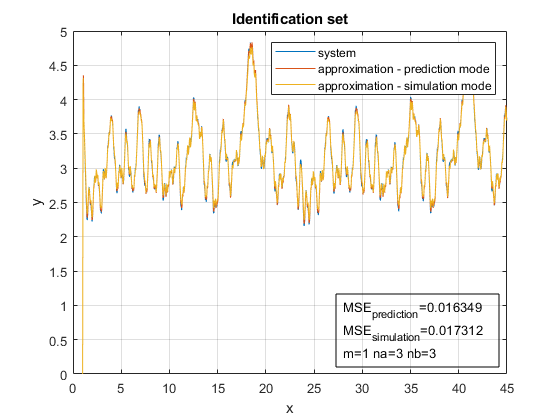

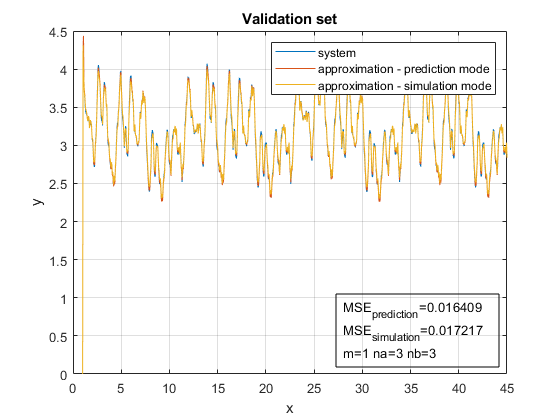

na = 3; nb = 3; m = 1;
%{
[~, best_index] = min(results.("mse valid sim")(:));
na = results.na(best_index);
nb = results.nb(best_index);
m = results.m(best_index);
%}

% prediction mode
theta_pred = get_theta(u_ident, y_ident, m, na, nb);

y_hat_ident_pred = get_y_hat(u_ident, y_ident, theta_pred, m, na, nb);
y_hat_valid_pred = get_y_hat(u_valid, y_valid, theta_pred, m, na, nb);

mse_ident_pred = get_mse(y_ident, y_hat_ident_pred);
mse_valid_pred = get_mse(y_valid, y_hat_valid_pred);


% simulation mode
theta_sim = get_theta(u_ident, y_hat_ident_pred, m, na, nb);

y_hat_ident_sim = get_y_hat(u_ident, y_ident, theta_sim, m, na, nb);
y_hat_valid_sim = get_y_hat(u_valid, y_valid, theta_sim, m, na, nb);

mse_ident_sim = get_mse(y_ident, y_hat_ident_sim);
mse_valid_sim = get_mse(y_valid, y_hat_valid_sim);

plot_comparison(Ts, m, na, nb, ...
                mse_ident_pred, mse_valid_pred, ...
                mse_ident_sim, mse_valid_sim, ...
                u_ident, y_ident, y_hat_ident_pred, y_hat_ident_sim, ...
                u_valid, y_valid, y_hat_valid_pred, y_hat_valid_sim)

### The MSE for the validation set, in simulation mode, depending on the parameters

% remove the lines with mse >= 1
results_small_mse = results

results_small_mse = 41×8 table
    na    nb    m    nr parameters    mse ident pred    mse valid pred    mse ident sim    mse valid sim
    __    __    _    _____________    ______________    ______________    _____________    _____________

    1     1     1          3             0.024415          0.025563         0.024997         0.025768   
    2     1     1          4             0.022959          0.023514         0.025146         0.025446   
    3     1     1          5             0.022754          0.023175         0.024266         0.024163   
    1     2     1          4             0.019254          0.019743         0.019811         0.020161   
    2     2     1          5             0.017824          0.01801

for i = 1 : size(results_small_mse, 1)
    if results_small_mse.("mse valid sim")(i) >= 1
        results_small_mse.("mse valid sim")(i) = NaN;
    end
end
idx = find(isnan(results_small_mse.("mse valid sim")));
results_small_mse(idx, :) = []

results_small_mse = 12×8 table
    na    nb    m    nr parameters    mse ident pred    mse valid pred    mse ident sim    mse valid sim
    __    __    _    _____________    ______________    ______________    _____________    _____________

    1     1     1          3             0.024415          0.025563         0.024997         0.025768   
    2     1     1          4             0.022959          0.023514         0.025146         0.025446   
    3     1     1          5             0.022754          0.023175         0.024266         0.024163   
    1     2     1          4             0.019254          0.019743         0.019811         0.020161   
    2     2     1          5             0.017824          0.01801

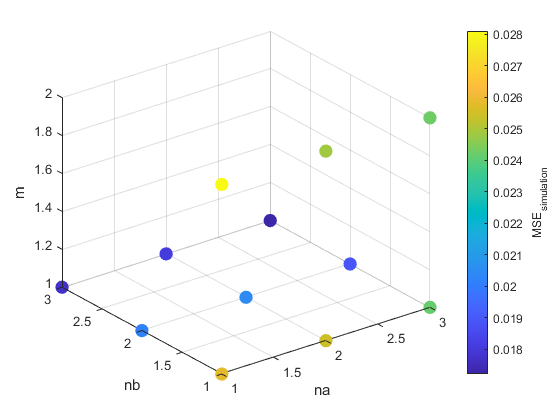

na = results_small_mse.na(:);
nb = results_small_mse.nb(:);
m = results_small_mse.m(:);
mse_valid_sim = results_small_mse.("mse valid sim")(:);
markerSize = 100;
scatter3(na, nb, m, markerSize, mse_valid_sim, 'filled');
markerSize = 100;
xlabel('na'); ylabel('nb'); zlabel('m');
cb = colorbar;
cb.Label.String = 'MSE_{simulation}';

### Functions

#### 1 - Function that retrieves the identification and validation data

Receives the name of a file and wether you want to make it zero-mean or not.

Returns the identification and validation data.

function [ident_data, valid_data, ...
          u_ident, y_ident, ...
          u_valid, y_valid, Ts] = get_data(file_name)

    experiment_data = load(file_name);
    ident_data = experiment_data.id;
    valid_data = experiment_data.val;
    
    Ts = experiment_data.id.Ts;
    
    u_ident = experiment_data.id.u;
    y_ident = experiment_data.id.y;
    
    u_valid = experiment_data.val.u;
    y_valid = experiment_data.val.y;
end

#### 2 - Function that makes the vector of delayed inputs OR outputs

Receives a row vector $\textrm{vect}$, a polynomial order $n$, and a number $k$.

Returns a vector of the form: $\left\lbrack \begin{array}{cccc}
\textrm{vect}\left(k-1\right) & \textrm{vect}\left(k-2\right) & \ldotp \ldotp \ldotp  & \textrm{vect}\left(k-n\right)
\end{array}\right\rbrack$ - $n$ terms


$$\textrm{vect}\left(k-n\right)=0\Leftrightarrow k\le n$$


function vector = get_delayed_vector(vect, n, k)
    vector = zeros(1, n);
    
    for i = 1 : n
        if k > i
            vector(i) = vect(k-i);
        else
            vector(i) = 0;
        end
    end
end

#### 3 - Function that makes the vector of delayed inputs AND outputs

Receives the row vectors for output, $y$, and input, $u$. Also receives the polynomial orders $\textrm{na}$ and $\textrm{nb}$, and a number $k$.

Returns a vector of the form, with $\textrm{na}+\textrm{nb}$ terms$\left\lbrack \begin{array}{cccccccc}
-y\left(k-1\right) & -y\left(k-2\right) & \ldotp \ldotp \ldotp  & -y\left(k-\textrm{na}\right) & u\left(k-1\right) & u\left(k-2\right) & \ldotp \ldotp \ldotp  & u\left(k-\textrm{nb}\right)
\end{array}\right\rbrack$

function vector = get_delayed_io(y, u, na, nb, k)
    delayed_inputs = get_delayed_vector(-y, na, k);
    delayed_outputs = get_delayed_vector(u, nb, k);
    vector = [delayed_inputs delayed_outputs];
end

#### 4 - Function that finds the polynomial of degree $m$ in $n$ variables $x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_n$

Receives the degree of the polynomial $m$ and  the vector of variables $X$.

Returns a vector containing the terms of the polynomial.

For example: 

        
$$\begin{array}{l}
m=2,\;X=\left\lbrack \begin{array}{cc}
x_1  & x_2 
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\Rightarrow \textrm{poly}=\left(\begin{array}{cccccc}
1 & x_1  & x_2  & x_1 \,x_2  & {x_1 }^2  & {x_2 }^2 
\end{array}\right)\\
m=3,\;X=\left\lbrack \begin{array}{cc}
x_1  & x_2 
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\Rightarrow \textrm{poly}=\left(\begin{array}{cccccccccc}
1 & x_1  & x_2  & x_1 \,x_2  & x_1 \,{x_2 }^2  & {x_1 }^2 \,x_2  & {x_1 }^2  & {x_1 }^3  & {x_2 }^2  & {x_2 }^3 
\end{array}\right)\\
m=2,\;X=\left\lbrack \begin{array}{ccc}
x_1  & x_2  & x_3 
\end{array}\right\rbrack \Rightarrow \textrm{poly}=\left(\begin{array}{cccccccccc}
1 & x_1  & x_2  & x_3  & x_1 \,x_2  & x_1 \,x_3  & x_2 \,x_3  & {x_1 }^2  & {x_2 }^2  & {x_3 }^2 
\end{array}\right)
\end{array}$$


function poly = get_poly(m, X)
    X_syms = (sym('x',[1 size(X, 2)]));
    
    expr = 1;
    for i = 1 : m
        expr = expr + sum(X_syms)^i;
    end
    
    [~, powers] = coeffs(expr);
    poly = sort(powers); % display this for the syms form
    poly = subs(poly, sym2cell(X_syms), num2cell(X));
    poly = double(poly);
end

#### 5 - Function that computes the matrix $\Phi$ 

Each row is a polynomial in $\textrm{na}+\textrm{nb}$ variables of degree $m$, i.e.:


$$\begin{array}{l}
\Phi \left(k,:\right)={\left(\sum_{i=1}^{\textrm{na}+\textrm{nb}} x_i \right)}^m \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;={\left(x_1 +x_2 +\ldotp \ldotp \ldotp +x_{\textrm{na}} +x_{\textrm{na}+1} +x_{\textrm{na}+2} +\ldotp \ldotp \ldotp +x_{\textrm{na}+\textrm{nb}} \right)}^m \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;={\left(-y_{k-1} \;-y_{k-2} \;-\ldotp \ldotp \ldotp -y_{k-\textrm{na}} \;+u_{k-1} +u_{k-2} +\ldotp \ldotp \ldotp +u_{k-\textrm{nb}} \;\right)}^m 
\end{array}$$


The number of terms of such a polynomial is:


$$n=C_m^{\textrm{na}+\textrm{nb}+m} =\frac{\left(\textrm{na}+\textrm{nb}+m\right)!}{m!\;\left(\textrm{na}+\textrm{nb}\right)!}$$


https://mathoverflow.net/questions/225953/number-of-polynomial-terms-for-certain-degree-and-certain-number-of-variables

function phi = get_phi(u, y, m, na, nb)
    N = size(u, 1);
    n = nchoosek(na+nb+m, m);
    phi = zeros(N, n);
    
    for k = 1 : N
        if (k-1 <= 0)
            phi(k, 1:end) = zeros(1, n);
        else
            delayed_io = get_delayed_io(y, u, na, nb, k);
            phi(k, 1:end) = get_poly(m, delayed_io);
            %phi(k, 1:end) = get_poly(m, [-y(k-1) u(k-1)]);
        end
    end
end

#### 6 - Function that computes the vector $\theta$

function theta = get_theta(u_ident, y_ident, m, na, nb)
    phi = get_phi(u_ident, y_ident, m, na, nb);
    theta = phi\y_ident;
end

#### 7 - Function that computes $\hat{y}$

Receives the identification/ validation data, $u$ and $y$, the parameters $\theta$ and the polynomial orders $\textrm{na}$ and $\textrm{nb}$.

Returns the approximated function $y_{\textrm{hat}}$.

function y_hat = get_y_hat(u, y, theta, m, na, nb)
    phi = get_phi(u, y, m, na, nb);
    y_hat = phi * theta;
end

#### 8 - Function that computes the MSE

function mse = get_mse(y, y_hat)
    mse = mean((y - y_hat).^2);
end

#### 9 - Function that finds all the possible combinations $\textrm{na}$, $\textrm{nb}$ and $m$

When tuning the results, the number of parameters must not be too large for our dataset, i.e.:

        
$$\begin{array}{l}
\textrm{number}\;\textrm{of}\;\textrm{parameters}\le 0\ldotp 2\cdot \textrm{number}\;\textrm{of}\;\textrm{data}\;\textrm{samples}\\
\textrm{number}\;\textrm{of}\;\textrm{parameters}=n=C_m^{\textrm{na}+\textrm{nb}+m} =\frac{\left(\textrm{na}+\textrm{nb}+m\right)!}{m!\;\left(\textrm{na}+\textrm{nb}\right)!}\\
\textrm{number}\;\textrm{of}\;\textrm{data}\;\textrm{samples}=N=1000
\end{array}$$


For $\textrm{na},\textrm{nb},m\in \left\lbrace 1,2,3,\ldotp \ldotp \ldotp ,\max \right\rbrace$, returns a matrix with the following columns: $\left\lbrack \begin{array}{cccc}
\textrm{na} & \textrm{nb} & m & n
\end{array}\right\rbrack$.

function combs = get_param_combs(max_na_nb, max_m, N)
    na = 1 : max_na_nb;
    nb = 1 : max_na_nb;
    m = 1 : max_m;
    
    [ca, cb, cc] = ndgrid(na, nb, m);
    combs = [ca(:), cb(:), cc(:)];
    combs = [combs zeros(size(combs, 1), 1)];
    for i = 1 : size(combs, 1)
        combs(i, end) = nchoosek(combs(i, 1) + combs(i, 2) + combs(i, 3), combs(i, 3)); 
    end
    combs = combs(all(combs(:, end) <= 0.2*N, 2), :);
end

#### 10 - Plot approximated function for identification and validation data

function plot_comparison(Ts, m, na, nb, ...
                         mse_ident_pred, mse_valid_pred, ...
                         mse_ident_sim, mse_valid_sim, ...
                         u_ident, y_ident, y_hat_ident_pred, y_hat_ident_sim, ...
                         u_valid, y_valid, y_hat_valid_pred, y_hat_valid_sim)
    figure,
    t_ident = linspace(1, size(u_ident, 1)*Ts, size(u_ident, 1));
    plot(t_ident, y_ident); grid; hold on;
    plot(t_ident, y_hat_ident_pred); 
    plot(t_ident, y_hat_ident_sim); hold off;
    xlabel('x'); ylabel('y'); 
    legend('system', 'approximation - prediction mode', 'approximation - simulation mode');
    title('Identification set');
    
    str = [convertCharsToStrings(['MSE_{prediction}=', num2str(mse_ident_pred)]); ...
           convertCharsToStrings(['MSE_{simulation}=', num2str(mse_ident_sim)]); ...
           convertCharsToStrings(['m=', num2str(m), ' na=', num2str(na), ' nb=', num2str(nb)])];
    annotation('textbox',[.6 .2 .1 .1],'String',str,'FitBoxToText','on');
    
    
    figure,
    t_valid = linspace(1, size(u_valid, 1)*Ts, size(u_valid, 1));
    plot(t_valid, y_valid); grid; hold on;
    plot(t_valid, y_hat_valid_pred); 
    plot(t_valid, y_hat_valid_sim); hold off;
    xlabel('x'); ylabel('y'); 
    legend('system', 'approximation - prediction mode', 'approximation - simulation mode');
    title('Validation set');
    
    str = [convertCharsToStrings(['MSE_{prediction}=', num2str(mse_valid_pred)]); ...
           convertCharsToStrings(['MSE_{simulation}=', num2str(mse_valid_sim)]); ...
           convertCharsToStrings(['m=', num2str(m), ' na=', num2str(na), ' nb=', num2str(nb)])];
    annotation('textbox',[.6 .2 .1 .1],'String',str,'FitBoxToText','on');
end